12.12)

(c)

figure(1);
% initialize
N = 10;
K = 4;
L = 13;
e = [[1,3];[1,4];[1,7];[2,3];[2,5];[2,8];[2,9];[3,4];[3,5];[4,6];
    [5,6];[6,9];[6,10]];
known = [[0,0];[0,1];[1,1];[1,0]];
uv = [known(:,1); known(:,2)];
% fill in incidence matrix
M = zeros(L, N);
for i = 1:13
    M(i,e(i,1)) = 1;
    M(i,e(i,2)) = -1;
end
% note that every row of M has a 1 and a -1. This is just for the
% distance formula to work.
A1 = M(:,1:(N-K));
% these are just the outgoing edges for the non-fixed points
A = [A1, zeros(size(A1)); zeros(size(A1)), A1];
B1 = abs(M(:,N-K+1:N));
% b is all the fixed points ends of the edges in question
b = [B1, zeros(size(B1)); zeros(size(B1)), B1] * uv;
% solve the linear regression equation
x = A \ b;
% plot
hold on;
all = [[x(1:N-K) x(N-K+1:end)]; known]

all =     0.3553    0.3480
    0.5311    0.7985
    0.5128    0.5641
    0.5531    0.4799
    0.6117    0.6300
    0.7912    0.5275
         0         0
         0    1.0000
    1.0000    1.0000
    1.0000         0


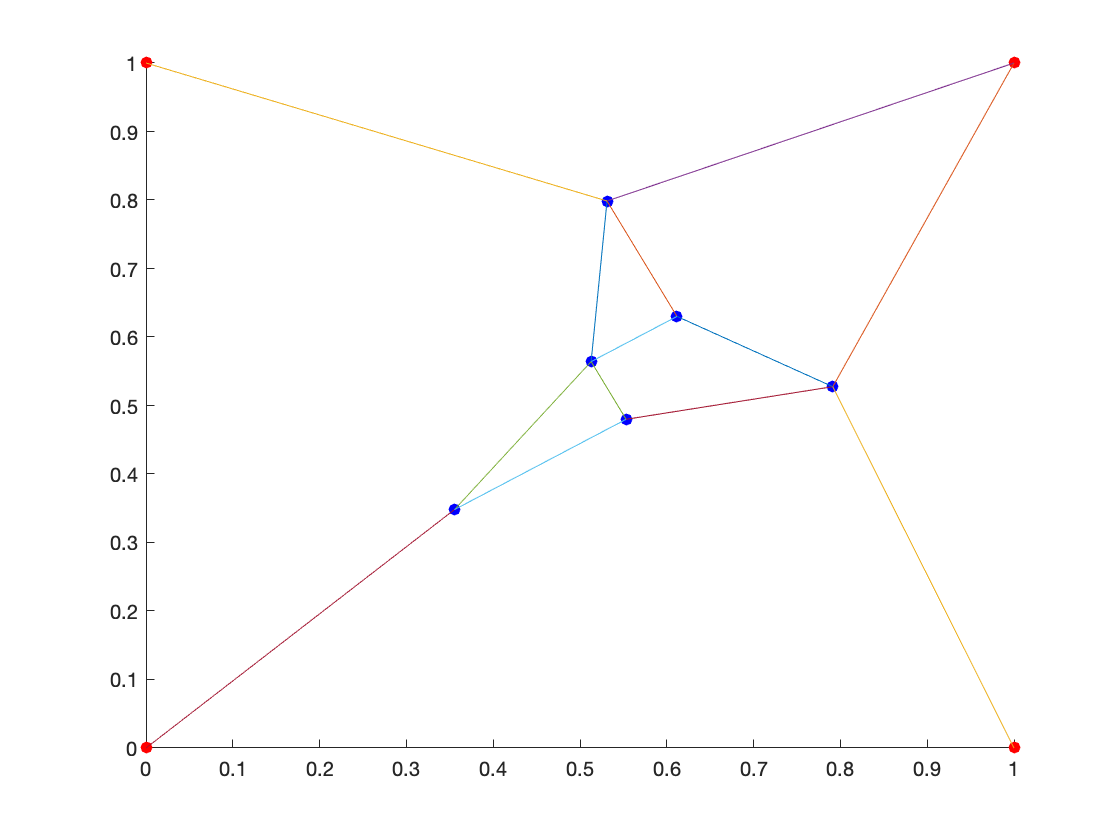

scatter(all(1:N-K,1), all(1:N-K,2), 'filled', 'blue');
scatter(all(N-K+1:end,1), all(N-K+1:end,2), 'filled', 'red');
for edge = 1:13
    pA = all(e(edge,1),:);
    pB = all(e(edge,2),:);
    plot([pA(1) pB(1)], [pA(2) pB(2)]);
end

13.3)

(a)

figure(2);
hold on;
mooreslaw
scatter(T(:,1), T(:,2));
set(gca, 'yscale', 'log')

n = length(T);
A = [ones(n, 1) T(:,1)-1970];
y = log(T(:,2))/log(10);

% trying to minimize
w = A \ y;

theta1 = w(1)

theta1 = 3.1256

theta2 = w(2)

theta2 = 0.1540

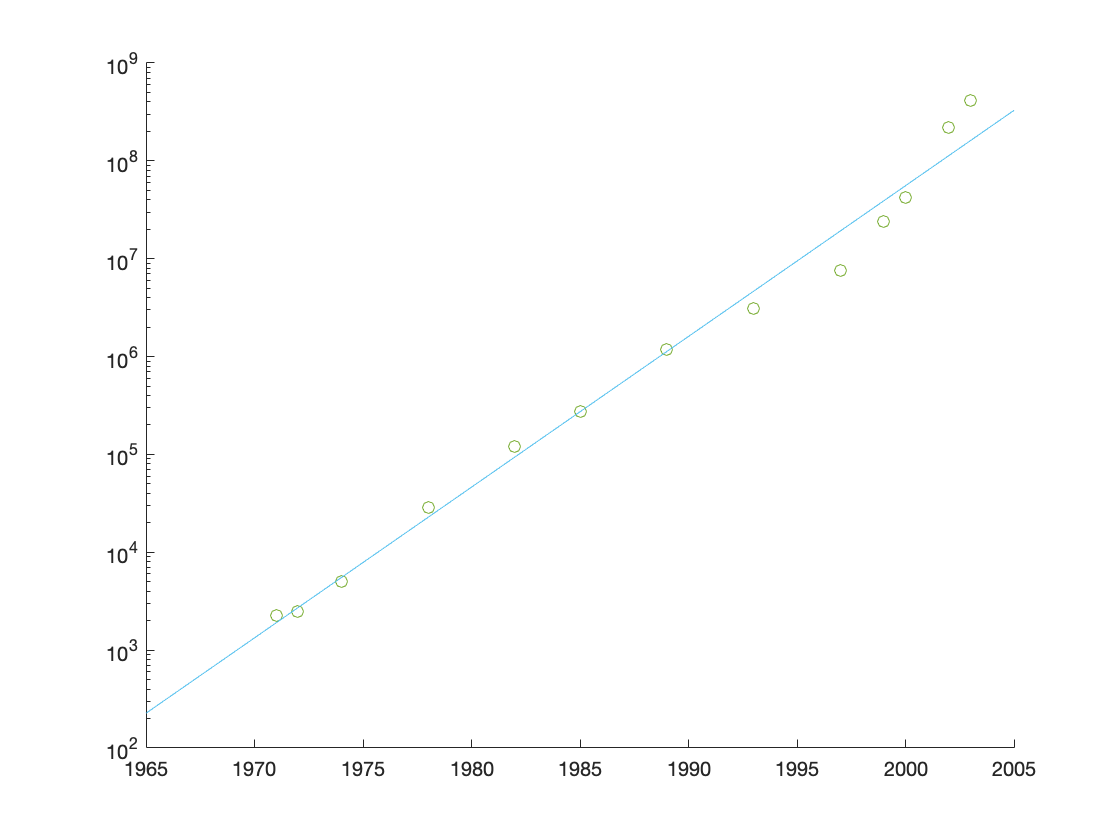


x = (1965:1:2005);
plot(x, 10.^((x-1970) * theta2 + theta1));

(b)

tran_2015 = 10.^((2015-1970) * theta2 + theta1)

tran_2015 = 1.1387e+10

acc_ratio = tran_2015 / (4 * 10^9)

acc_ratio = 2.8468

(c)

rate20 = log(2)/(log(10) * theta2)

rate20 = 1.9545

8.3)

figure(3);
hold on;
[t, y] = logistic_fit;
n = length(t);
scatter(t, y);
A = [ones(n, 1) t];
b = log(y ./ (1 - y));
w = A \ b;
alpha = w(2)

alpha = 1.8676

beta = w(1)

beta = -3.7397

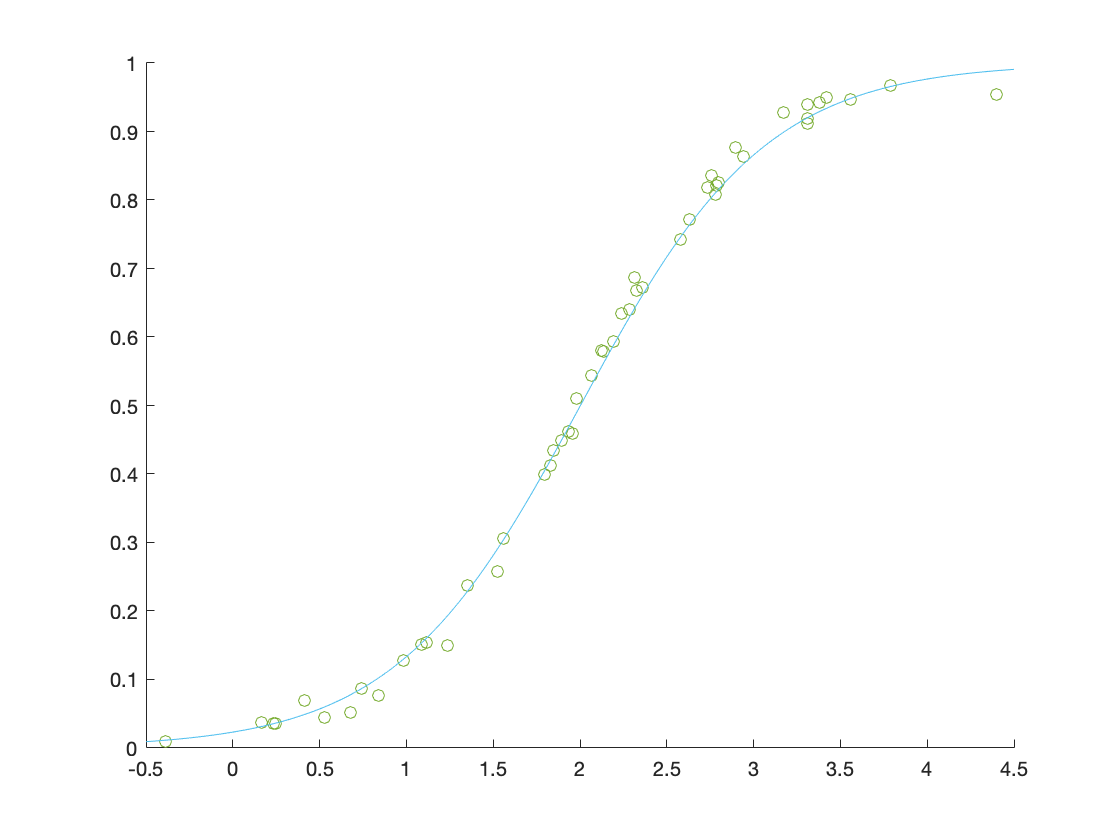

x = (-0.5:0.01:4.5);
plot(x, (exp(alpha * x + beta) ./ (1 + exp(alpha * x + beta))));